clf
plot(act6); 
hold on; 
plot(discrete_filt(act6,50,10))

A =
 
     0.9933
  ------------
  z - 0.006738
 
Sample time: 0.1 seconds
Discrete-time transfer function.



alpha = 0.9933

beta = 0.0067

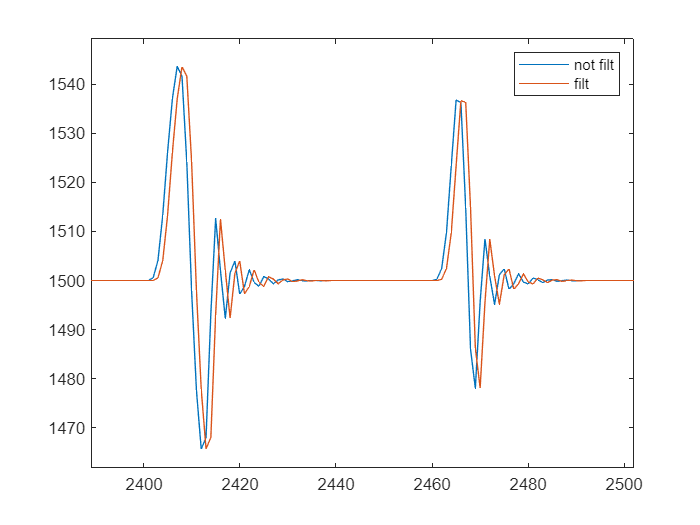

legend("not filt", "filt")

plot(t_acc(2:end),a_p);hold on; plot(t_acc(2:end),a_q);legend("p","q")

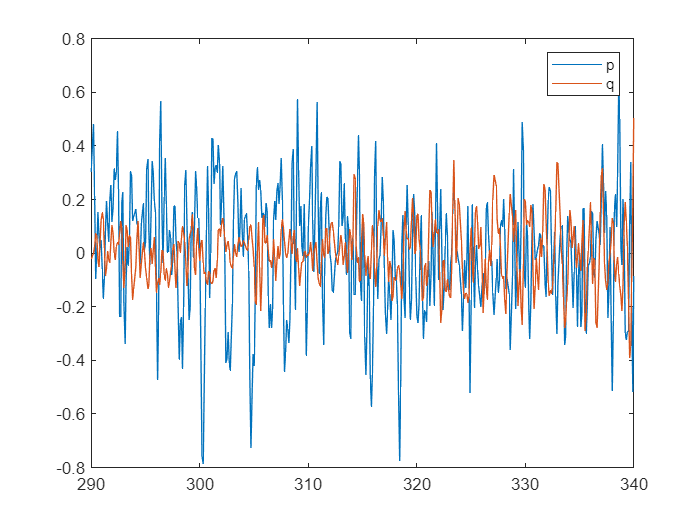

figure(500)
clf
plot(t_acc,low_butter(p,f_filter,sf_acc,0));hold on; plot(t_acc,low_butter(q,f_filter,sf_acc,0));legend("p","q")
xlim([290,340])

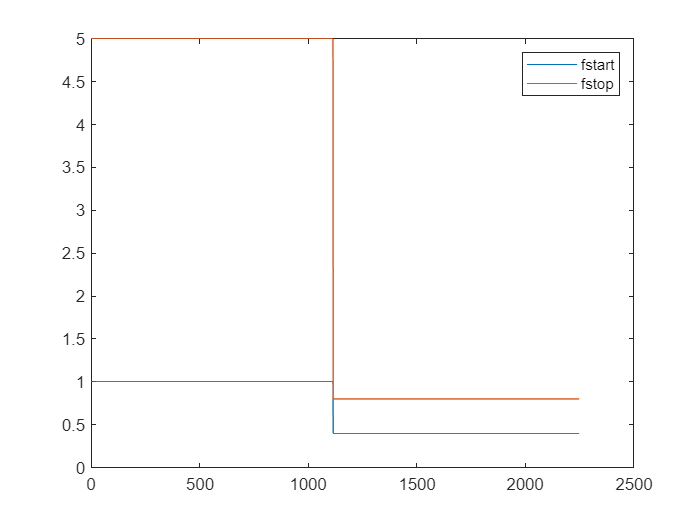

yyy = fft(a_p(t_acc<315)-mean(a_p(t_acc<315)));
yy = fft(a_p(t_acc(2:end)>=315)-mean(a_p(t_acc(2:end)>=315)));

n = length(yyy);          % number of samples
n2 = length(yy);
fs = 10;
f = (0:n-1)*(fs/n);     % frequency range
f2 = (0:n2-1)*(fs/n2); 
power_yyy = abs(yyy).^2/n;    % power of the DFT
power_yy = abs(yy).^2/n2;

xxx = fft(a_q(t_acc<315)-mean(a_q(t_acc<315)));
xx = fft(a_q(t_acc(2:end)>=315)-mean(a_q(t_acc(2:end)>=315)));

n = length(xxx);          % number of samples
n2 = length(xx);
fs = 10;
f = (0:n-1)*(fs/n);     % frequency range
f2 = (0:n2-1)*(fs/n2); 
power_xxx = abs(xxx).^2/n;    % power of the DFT
power_xx = abs(xx).^2/n2;

figure(503)
clf
plot(ac_data.CHIRP.fstart)
hold on
plot(ac_data.CHIRP.fstop)
legend("fstart","fstop")

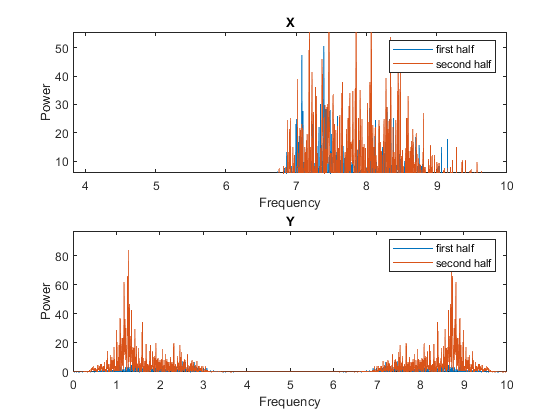


figure(501)
clf
subplot(2,1,1)
plot(f,power_yyy)
hold on
plot(f2,power_yy)
legend("first half","second half")
xlabel('Frequency')
ylabel('Power')
title('X')

subplot(2,1,2)
plot(f,power_xxx)
hold on
plot(f2,power_xx)
legend("first half","second half")
xlabel('Frequency')
ylabel('Power')
title('Y')

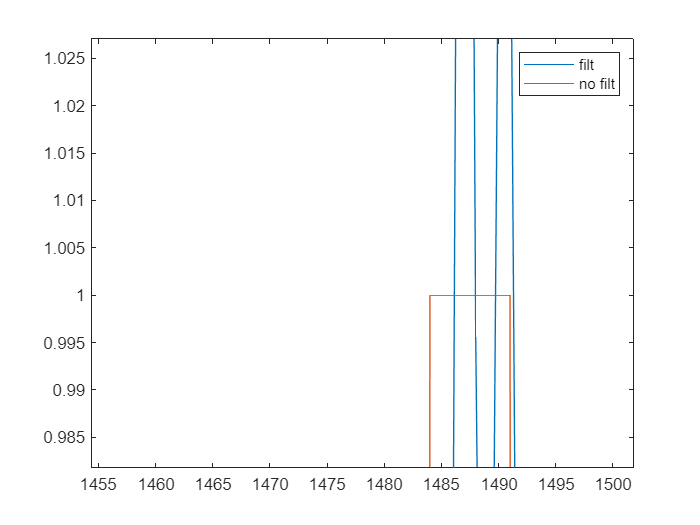

figure(505)
clf
plot(dou_active)
hold on
plot(ac_data.DOUBLET.doublet_active)
legend("filt","no filt")